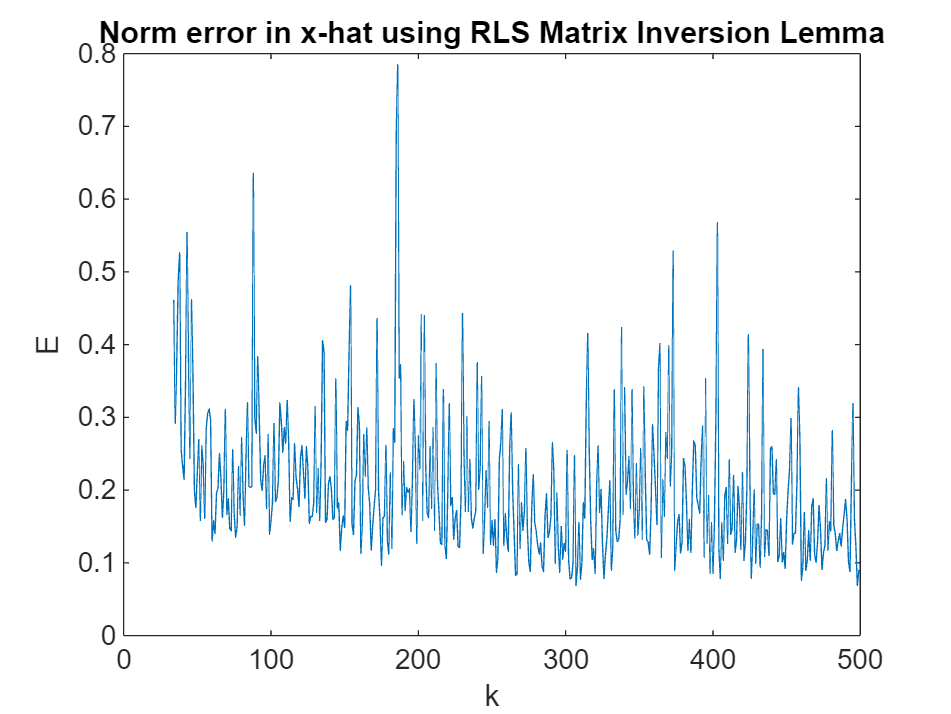

%HW 7 Q4d
tic
close all
clear 
clc
load("DataHW07_Prob4.mat")
temp = cell2mat(C(1));
temp_1 = size(temp);
n = ceil(temp_1(2)/temp_1(1));
S = eye(3);
for i = 1:n
    if (i == 1)
        Qk = cell2mat(C(1))'*eye(3)*cell2mat(C(1));
        Tk = cell2mat(C(1))'*eye(3)*cell2mat(y(1));
    else
        Qk = Qk + cell2mat(C(i))'*eye(3)*cell2mat(C(i));
        Tk = Tk + cell2mat(C(i))'*eye(3)*cell2mat(y(i));
    end
end
Pk = inv(Qk);
x_k_hat = Pk*Tk;

for k = n:N-1
    Pk1 = Pk - Pk*cell2mat(C(k+1))'*inv(inv(S)...
        + cell2mat(C(k+1))*Pk*cell2mat(C(k+1))')*cell2mat(C(k+1))*Pk;
    Kk1 = Pk1 * cell2mat(C(k+1))' * S;
    Xk1 =x_k_hat + Kk1*(cell2mat(y(k+1))-cell2mat(C(k+1))*x_k_hat);
    x_k_hat = Xk1;

    Ek_temp = x_k_hat - cell2mat(x_actual(k));
    Ek_temp1 = Ek_temp.^2;
    if (k == n)
    Ek = sum(Ek_temp1)^0.5;
    else
    Ek = [Ek;(sum(Ek_temp1))^0.5];
    end
end
plot(n:N-1,Ek)
title('Norm error in x-hat using RLS Matrix Inversion Lemma')
xlabel('k')
ylabel('E')

toc

Elapsed time is 0.131495 seconds.
